# Deep learning for classification on the MNIST dataset

Copyright 2018 The MathWorks, Inc.

## Prepare the dataset

In this example, we will perform image classification using deep learning (from scratch) on the MNIST dataset. The MNIST dataset is a set of handwritten digits categorized 0-9 and is available at [http://yann.lecun.com/exdb/mnist/.](http://yann.lecun.com/exdb/mnist/.)

The following line will download (if necessary) and prepare the dataset to use in MATLAB.

[imgDataTrain, labelsTrain, imgDataTest, labelsTest] = prepareData;

Preparing MNIST data...
MNIST data preparation complete.


## Let's look at a few of the images

We will pick a random sampling of the images to take a closer look.

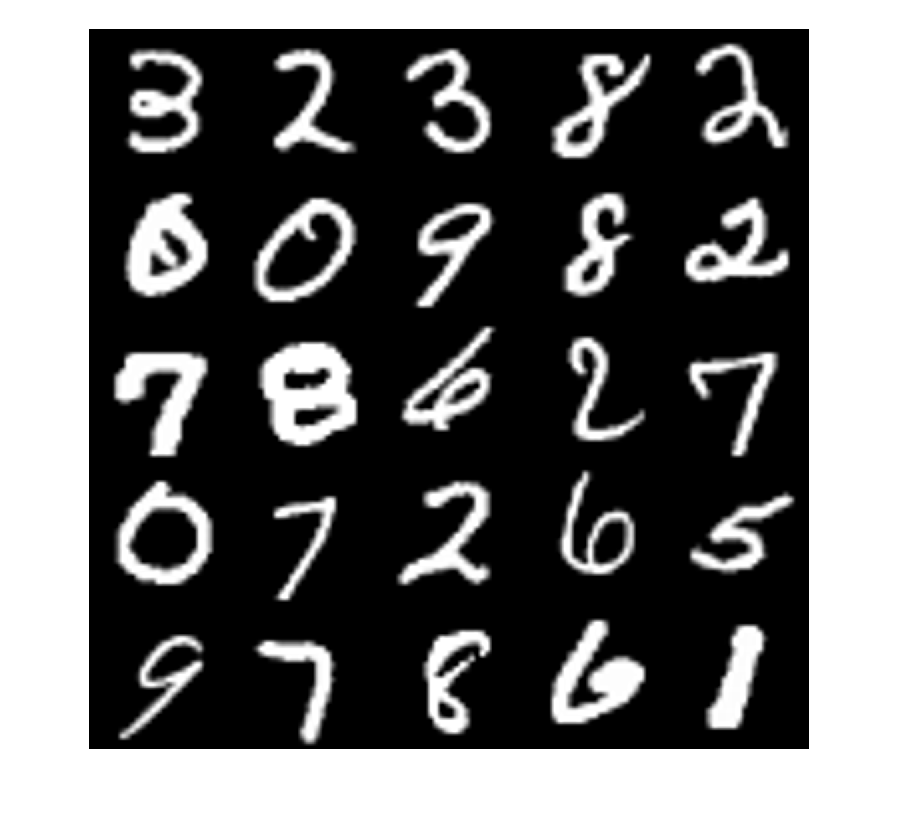

warning off images:imshow:magnificationMustBeFitForDockedFigure
perm = randperm(numel(labelsTrain), 25);
subset = imgDataTrain(:,:,1,perm);
montage(subset)

## How do we classify a digit?

We'll start with the end goal first, and use a model already trained to classify images with MNIST, so we can see what we're trying to achieve.

**Note: **You can execute this section of the script multiple times and get a random classification image each time.

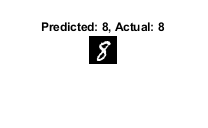

load MNISTModel

% Predict the class of an image
randIndx = randi(numel(labelsTest));
img = imgDataTest(:,:,1,randIndx);
actualLabel = labelsTest(randIndx);

predictedLabel = net.classify(img);
imshow(img);
title(['Predicted: ' char(predictedLabel) ', Actual: ' char(actualLabel)])

## Need a starting point? Check the documentation!

Search "deep learning" in the documentation for more.

Here is a specific article that talks about the task we are doing here.

web(fullfile(docroot, 'nnet/deep-learning-training-from-scratch.html'))

## Prepare the CNN

We found an example of a convolutional neural network (CNN) in the documentation. One of the simplest possible convnets, it contains one convolutional layer, one ReLU, one pooling layer, and one fully connected layer. Let's utilize it as our first attempt at classifying these images.

layers = [  imageInputLayer([28 28 1])
            convolution2dLayer(5,20)
            reluLayer
            maxPooling2dLayer(2, 'Stride', 2)
            fullyConnectedLayer(10)
            softmaxLayer
            classificationLayer()   ]

layers =   7x1 Layer array with layers:

     1   ''   Image Input             28x28x1 images with 'zerocenter' normalization
     2   ''   Convolution             20 5x5 convolutions with stride [1  1] and padding [0  0  0  0]
     3   ''   ReLU                    ReLU
     4   ''   Max Pooling             2x2 max pooling with stride [2  2] and padding [0  0  0  0]
     5   ''   Fully Connected         10 fully connected layer
     6   ''   Softmax                 softmax
     7   ''   Classification Output   crossentropyex

miniBatchSize = 1000;        
        

## Attempt 1: Set training options and train the network

Let's use default values (except for miniBatchSize, which controls the memory of the computations) and try training this network.

Training on single GPU.
Initializing input data normalization.


|========================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Mini-batch  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |     Loss     |      Rate       |
|========================================================================================|


|       1 |           1 |       00:00:01 |        9.50% |      13.9490 |          0.0100 |


|       1 |          50 |       00:00:22 |       10.00% |          NaN |          0.0100 |


|       2 |          64 |       00:00:28 |       10.70% |          NaN |          0.0100 |
|========================================================================================|


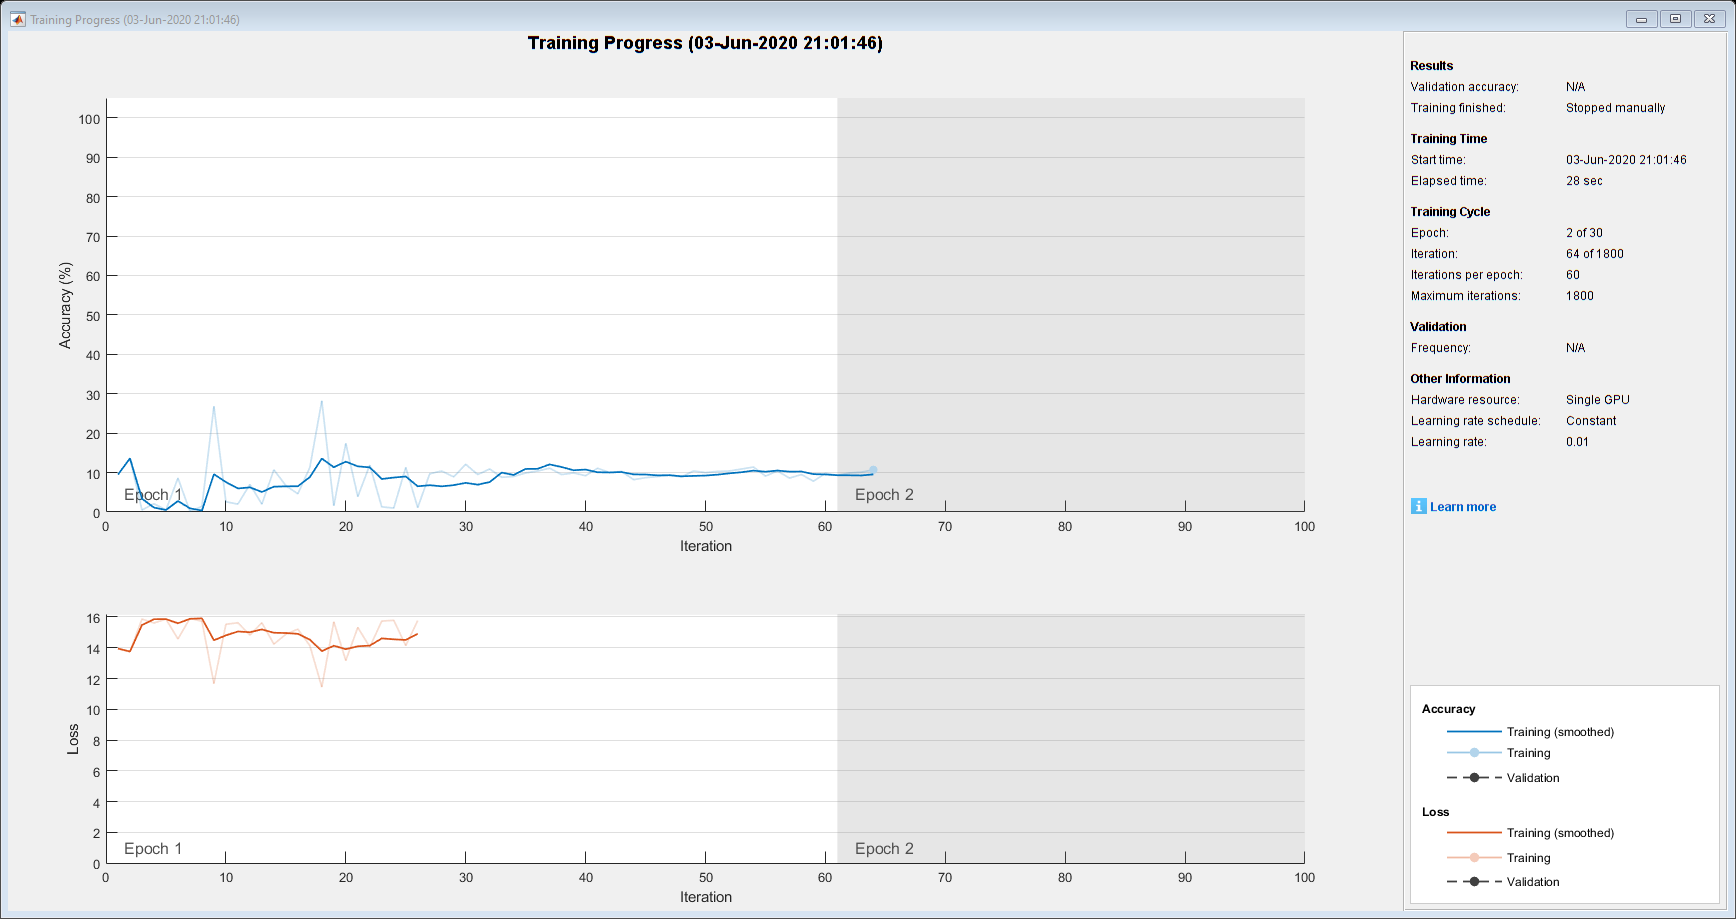


options = trainingOptions( 'sgdm',...
    'MiniBatchSize', miniBatchSize,...
    'Plots', 'training-progress');

net = trainNetwork(imgDataTrain, labelsTrain, layers, options);

## Attempt 2: Change the learning rate

That didn't work too well. Let's try changing one of the main parameters that affects neural network training: the **learning rate.**

Training on single GPU.
Initializing input data normalization.


|========================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Mini-batch  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |     Loss     |      Rate       |
|========================================================================================|


|       1 |           1 |       00:00:00 |        7.90% |      13.9302 |      1.0000e-04 |


|       1 |          50 |       00:00:08 |       88.40% |       1.0725 |      1.0000e-04 |


|       2 |         100 |       00:00:16 |       90.30% |       0.6352 |      1.0000e-04 |


|       3 |         150 |       00:00:25 |       91.30% |       0.6120 |      1.0000e-04 |


|       4 |         200 |       00:00:33 |       92.40% |       0.5214 |      1.0000e-04 |


|       5 |         250 |       00:00:41 |       93.10% |       0.4856 |      1.0000e-04 |


|       5 |         255 |       00:00:42 |       92.20% |       0.4852 |      1.0000e-04 |
|========================================================================================|


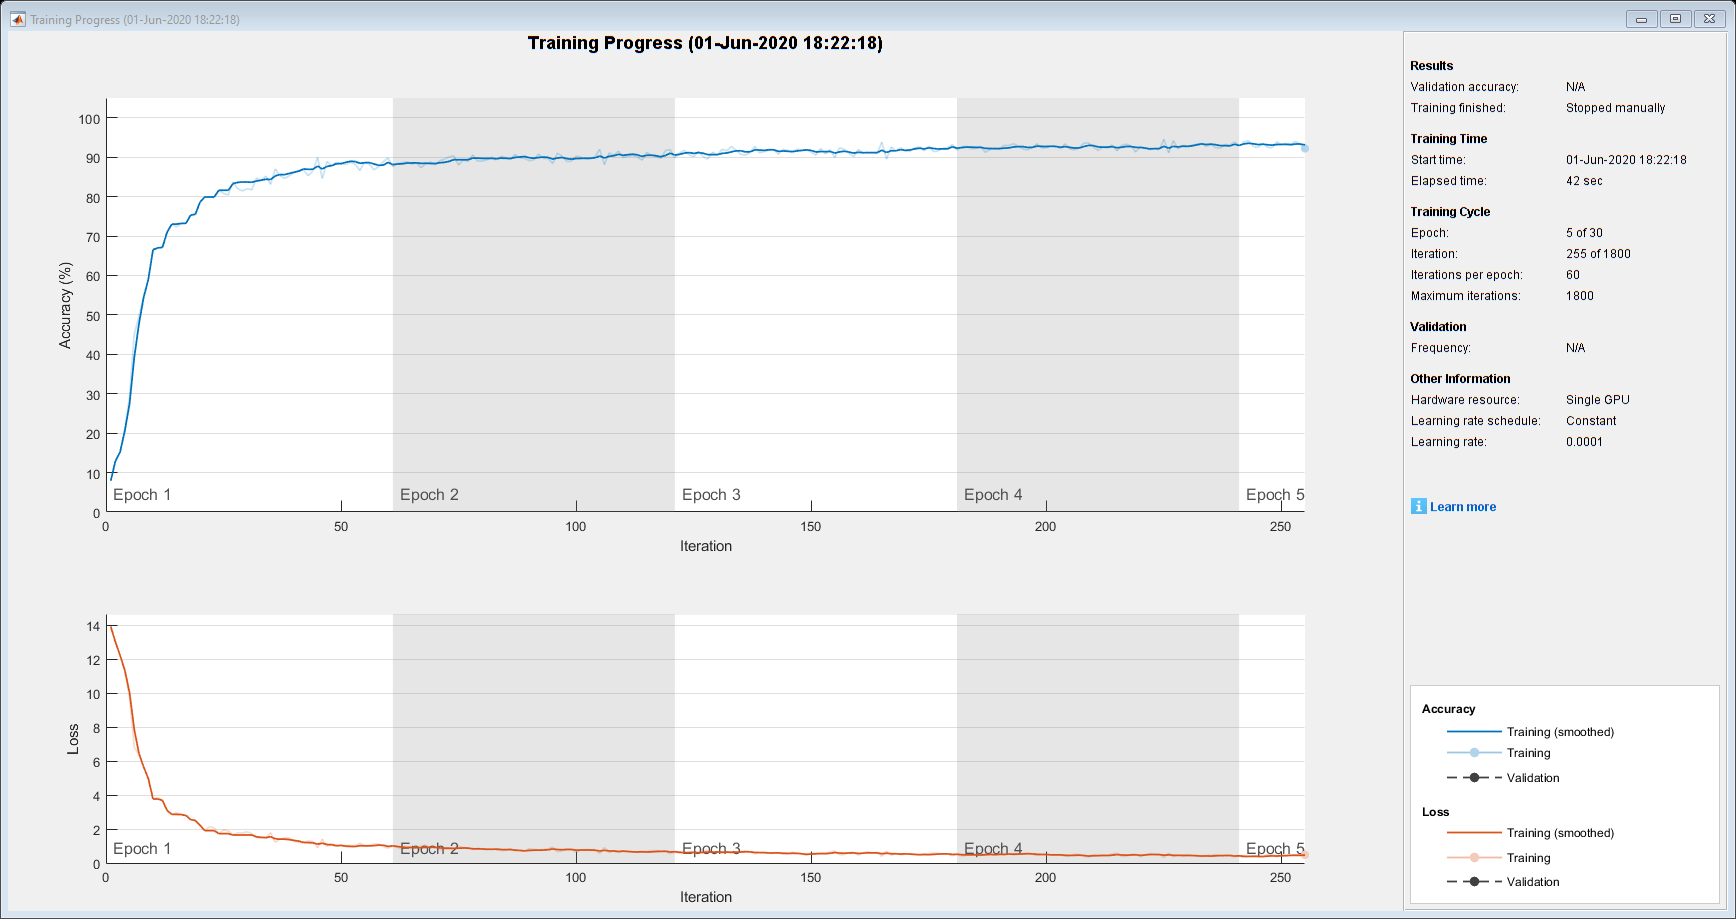

% options = trainingOptions( 'sgdm',...
%     'MiniBatchSize', miniBatchSize,...
%     'Plots', 'training-progress',...
%     'InitialLearnRate', 0.0001);
% 
% net = trainNetwork(imgDataTrain, labelsTrain, layers, options);

## Attempt 3: Change the network architecture

Sometimes, it's not the learning rate that needs changing. Other factors about the model can affect the training as well. Here, instead of playing with hyperparameters such as the learning rate, we can use a more sophisticated CNN in the first place. This one has multiple convolution layers, as well as **batch normalization** layers, which improve the quality and convergence rate of the training.

Training on single GPU.
Initializing input data normalization.


|========================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Mini-batch  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |     Loss     |      Rate       |
|========================================================================================|


|       1 |           1 |       00:00:04 |        5.00% |       2.9581 |          0.0100 |


|       1 |          50 |       00:00:46 |       96.50% |       0.1576 |          0.0100 |


|       2 |         100 |       00:01:26 |       97.00% |       0.1065 |          0.0100 |


|       3 |         150 |       00:02:07 |       97.60% |       0.0868 |          0.0100 |


|       4 |         200 |       00:02:47 |       97.30% |       0.0878 |          0.0100 |


|       5 |         250 |       00:03:27 |       97.70% |       0.0589 |          0.0100 |


|       5 |         300 |       00:04:07 |       98.90% |       0.0572 |          0.0100 |


|       6 |         350 |       00:04:48 |       98.80% |       0.0510 |          0.0100 |


|       7 |         400 |       00:05:28 |       98.10% |       0.0424 |          0.0100 |


|       8 |         450 |       00:06:08 |       98.60% |       0.0450 |          0.0100 |


|       9 |         500 |       00:06:49 |       98.50% |       0.0493 |          0.0100 |


|      10 |         550 |       00:07:32 |       99.10% |       0.0316 |          0.0100 |


|      10 |         600 |       00:08:12 |       99.20% |       0.0410 |          0.0100 |


|      11 |         650 |       00:08:52 |       99.00% |       0.0361 |          0.0100 |


|      12 |         700 |       00:09:32 |       98.80% |       0.0283 |          0.0100 |


|      13 |         750 |       00:10:12 |       99.20% |       0.0294 |          0.0100 |


|      14 |         800 |       00:10:52 |       98.90% |       0.0344 |          0.0100 |


|      15 |         850 |       00:11:33 |       99.30% |       0.0211 |          0.0100 |


|      15 |         900 |       00:12:13 |       99.60% |       0.0331 |          0.0100 |


|      16 |         950 |       00:12:54 |       99.20% |       0.0279 |          0.0100 |


|      17 |        1000 |       00:13:35 |       99.20% |       0.0205 |          0.0100 |


|      18 |        1050 |       00:14:16 |       99.40% |       0.0212 |          0.0100 |


|      19 |        1100 |       00:14:56 |       99.50% |       0.0261 |          0.0100 |


|      20 |        1150 |       00:15:37 |       99.50% |       0.0156 |          0.0100 |


|      20 |        1200 |       00:16:18 |       99.60% |       0.0274 |          0.0100 |


|      21 |        1250 |       00:16:58 |       99.30% |       0.0227 |          0.0100 |


|      22 |        1300 |       00:17:40 |       99.80% |       0.0156 |          0.0100 |


|      23 |        1350 |       00:18:20 |       99.70% |       0.0165 |          0.0100 |


|      24 |        1400 |       00:19:01 |       99.60% |       0.0206 |          0.0100 |


|      25 |        1450 |       00:19:42 |       99.90% |       0.0122 |          0.0100 |


|      25 |        1500 |       00:20:22 |       99.70% |       0.0225 |          0.0100 |


|      26 |        1550 |       00:21:04 |       99.60% |       0.0189 |          0.0100 |


|      27 |        1600 |       00:21:45 |      100.00% |       0.0124 |          0.0100 |


|      28 |        1650 |       00:22:26 |       99.80% |       0.0132 |          0.0100 |


|      29 |        1700 |       00:23:06 |       99.70% |       0.0168 |          0.0100 |


|      30 |        1750 |       00:23:47 |       99.90% |       0.0098 |          0.0100 |


|      30 |        1800 |       00:24:28 |       99.70% |       0.0185 |          0.0100 |


|========================================================================================|


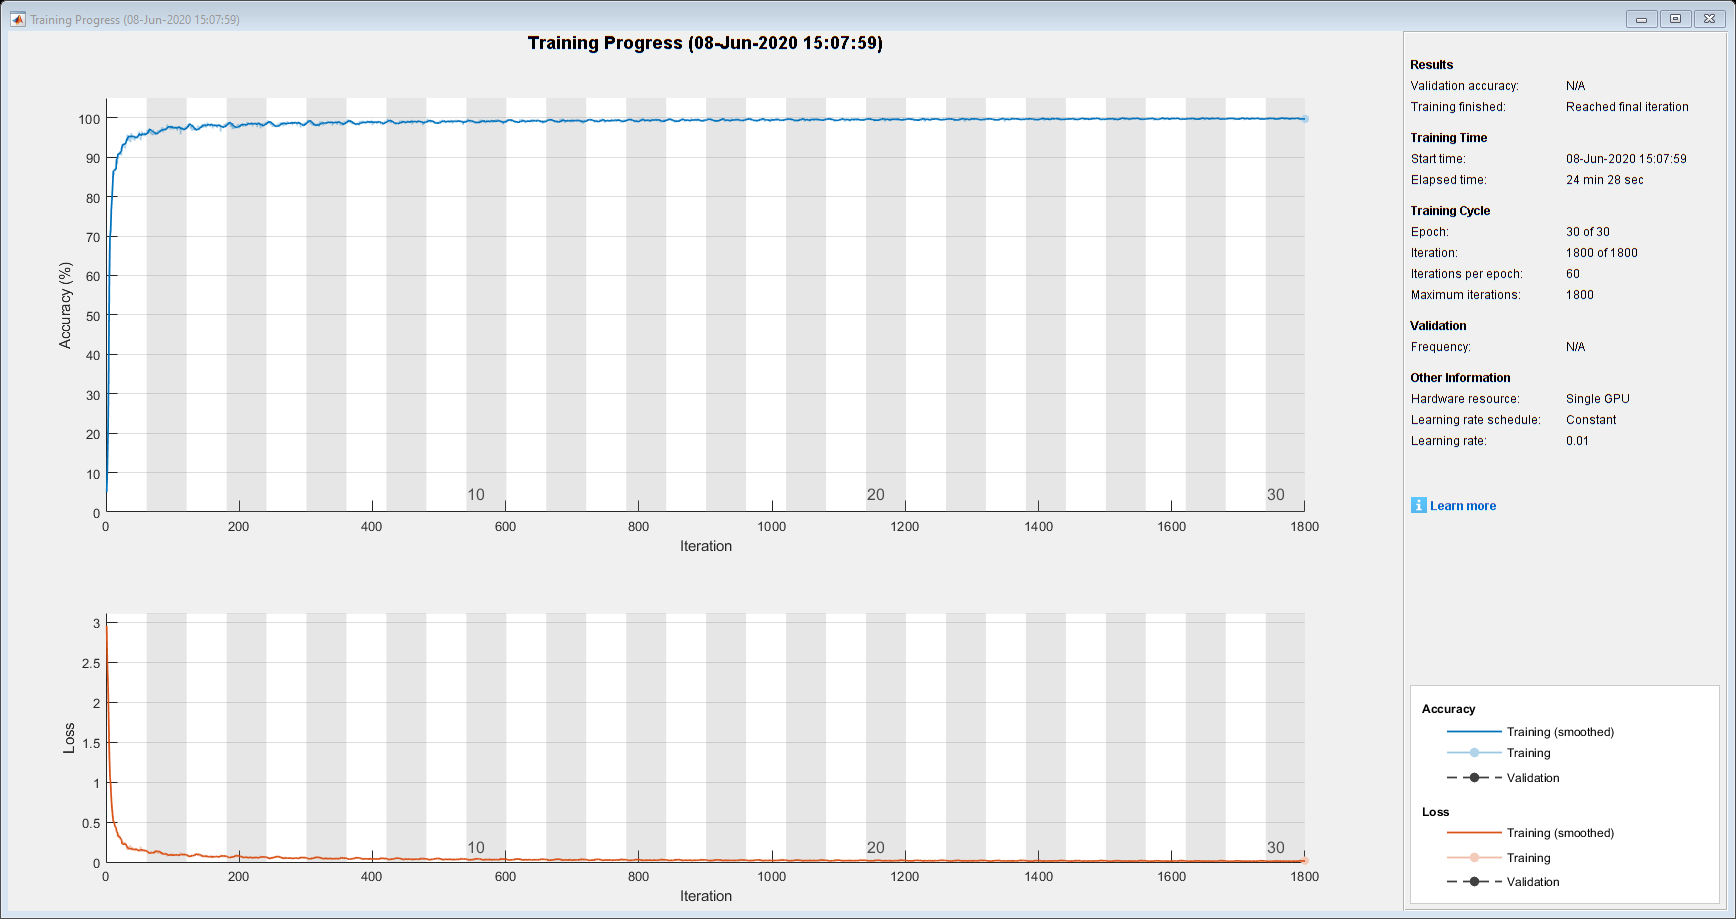

layers = [
    imageInputLayer([28 28 1])

    convolution2dLayer(3,16,'Padding',1)
    batchNormalizationLayer
    reluLayer

    maxPooling2dLayer(2,'Stride',2)

    convolution2dLayer(3,32,'Padding',1)
    batchNormalizationLayer
    reluLayer

    maxPooling2dLayer(2,'Stride',2)

    convolution2dLayer(3,64,'Padding',1)
    batchNormalizationLayer
    reluLayer

    fullyConnectedLayer(10)
    softmaxLayer
    classificationLayer];

options = trainingOptions( 'sgdm',...
    'MiniBatchSize', miniBatchSize,...
    'Plots', 'training-progress');

net = trainNetwork(imgDataTrain, labelsTrain, layers, options);

## Classify the test data set

We have a separate set of images in the MNIST dataset set aside specifically for testing. Let's use the test data to test the accuracy of the model we just trained.

predLabelsTest = net.classify(imgDataTest);

testAccuracy = sum(predLabelsTest == labelsTest) / numel(labelsTest)

testAccuracy = 0.9903

## Try to classify something else

Of course, we will need to come up with models for other types of data when the classifier fails.

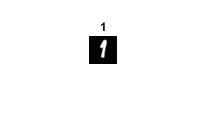

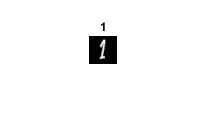

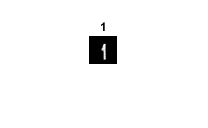

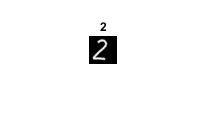

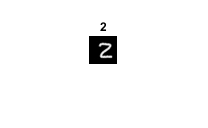

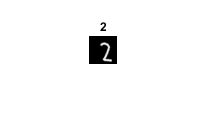

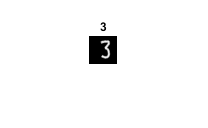

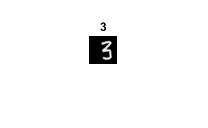

% % clear
% 
% camera = webcam; % Connect to the camera
% nnet = net;  % Load the neural net
% 
% % for frames = 1: 30   
%     picture = camera.snapshot;       
%     picture = rgb2gray(picture)% Take a picture    
%     picture = imresize(picture,[28,28]);  % Resize the picture
% 
%     label = classify(nnet, picture);        % Classify the picture
%        
%     image(picture);     % Show the picture
%     title(char(label)); % Show the label
%     drawnow;   
% end
% frame = [];
% v = VideoReader("MNISTTestVideo.mp4");
% for i = 1 : 23
%     frame = read(v,i);
%     frame = rgb2gray(frame);%
%     frame = imresize(frame, [28 28])
%     imgLabel = net.classify(frame);    
%     figure
%     imshow(frame)
%     title([net ' prediction: ' char(imgLabel)])
%     imshow(frame)
%     frame =[];
% end    
v = VideoReader("MNISTTestVideo50Frame.mp4");

numberOfFramesInspected = [1:1:50];

for i = 1 : length(numberOfFramesInspected)
    frame = read(v,numberOfFramesInspected(i));
    frame = rgb2gray(frame);
    frame = imresize(frame, [28 28]);
    imgLabel = net.classify(frame);    
    figure
    imshow(frame)
    title([char(imgLabel)])
%     imshow(frame)
end

acccuracy = 94% => 47/50























% img = imread('2.png');
% actualLabel = '2';
%     img = rgb2gray(img);
%     img = imresize(img, [28 28]);
% predictedLabel = net.classify(img);
% imshow(img);
% title(['Predicted: ' char(predictedLabel) ', Actual: ' char(actualLabel)])


% clear
% % Connect to the first webcam
% cam = webcam(1);
% 
% %% Single Image
% 
% % % Take a single image from cam
% % img = snapshot(camera);
% % % Display image
% % imshow(img)       
% while true   
%     picture = cam.snapshot;              % Take a picture    
%     picture = imresize(picture,[28,28]);  % Resize the picture
% 
%     label = classify(net, picture);        % Classify the picture
%        
%     image(picture);     % Show the picture
%     title(char(label)); % Show the label
%     drawnow;   
% end

%% Video

% % Loop 30 times
% for frames = 1:30        
%     % Take single image from cam
%     img = snapshot(cam);  
%     % Display image
%     imshow(img)       
% % End loop
% end                         

%% Classification

% % Load the pretrained GoogLeNet network
% nnet = googlenet;        
% % Loop 250 times
% for n = 1:250            
%     % Take single image
%     img = snapshot(cam);     
%     % Resize image to 224x224 pixels
%     img = imresize(img, [224, 224]);
%     % Classify image
%     [label, score] = classify(nnet, img);
%     % Display image
%     imshow(img)
%     % Show label, score
%     title({char(label), num2str(max(score),2)});
% % End loop
% end 
